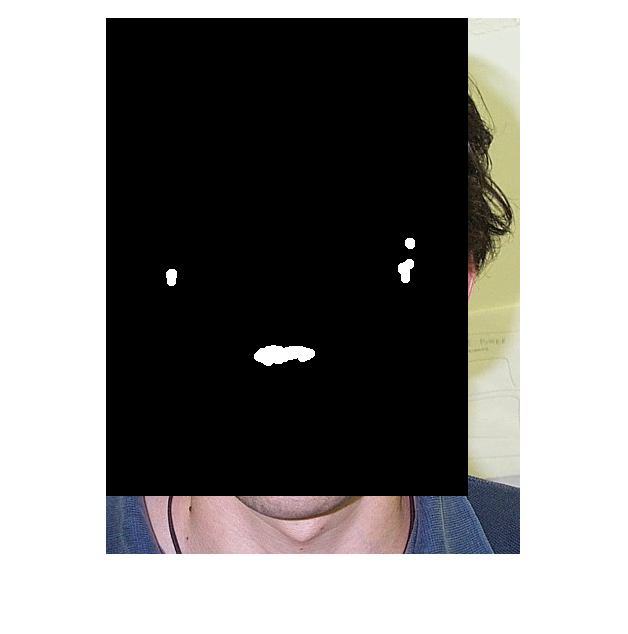

clear

% Read img file
img = imread("../db/DB1/db1_10.jpg");

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask((eyes),face_mask);
imshow(eye_mask)

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask)

x = 226

y = 305


[indexX,indexY] = eye_index(eye_mask)

indexX =    131   157   228


indexY =    225    70   222


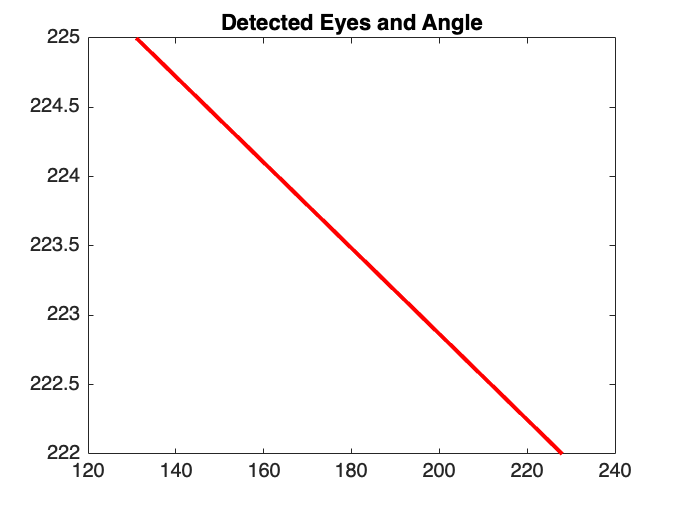

eye1 =    131   225


eye2 =    228   222


angle = -0.0309

% Replace with actual coordinates
mouth_center = [x, y]; 
[eye1 , eye2, angle] = findEyePair(indexX,indexY,mouth_center)

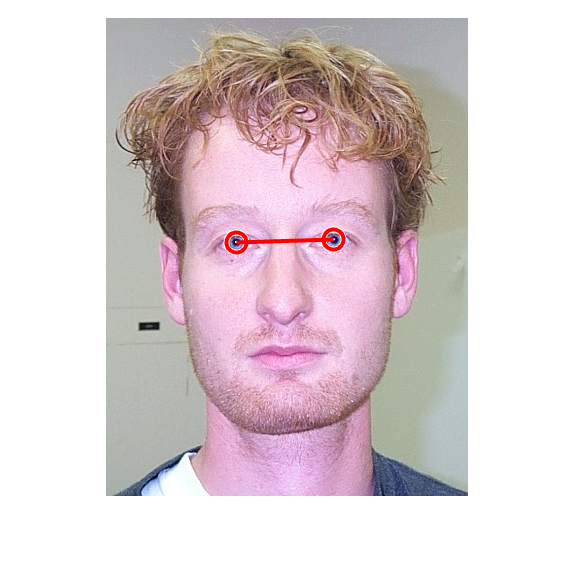


% Visualize the original image with detected eyes and mouth
figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')